%{
ES115- Class-Project Module 1 project bank
Author: Matthew Chietro
Version: 1.0
Date: 2026-04-13
Purpose:
    - To model and analyze the speed profile of an autonomous cart using a
      quadratic function of time.
    - To compute and visualize both speed and numerically estimated acceleration.
    - To determine when maximum speed occurs and estimate acceleration near that point.

Input:
    - Time vector from 0 to 20 seconds (t = 0:0.2:20)

Output:
    - Plot of speed vs time
    - Plot of acceleration vs time (numerical derivative)
    - Maximum speed value and corresponding time
    - Estimated acceleration near maximum speed printed to command window

Engineering Algorithms:
    - Define time vector using fixed step size (0.2 s)
    - Evaluate quadratic speed function v(t)
    - Plot speed vs time and mark midpoint (t = 10 s)
    - Compute time step dt
    - Use finite difference (diff) to approximate acceleration a(t) ≈ Δv/Δt
    - Align acceleration values to midpoint times
    - Plot acceleration vs time in separate figure
    - Find maximum speed using max()
    - Identify time index of maximum speed
    - Estimate acceleration near maximum speed using neighboring data point
    - Print results using fprintf

MATLAB tools/functions:
    - vector operations
    - plot, xlabel, ylabel, title, grid, xline
    - diff, max
    - fprintf
    - indexing and array slicing
    - figure
%}

Autonomous Cart Speed Profile (Quadratic + Numerical Change)

A small autonomous cart follows a speed profile over time modeled by:

v(t) = −0.2(t − 10)2 + 20

for 0 ≤ t ≤ 20 seconds.

Tasks

1. Implement v(t) and evaluate it on t = 0 : 0.2 : 20.

t = 0:0.2:20;           % time vector (seconds)
v = -0.2*(t - 10).^2 + 20;  % speed profile (m/s)

2. Plot speed vs time.

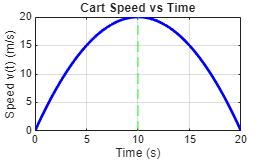

figure(1);
plot(t, v, 'b-', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Speed v(t) (m/s)');
title('Cart Speed vs Time');
xline(10,'g--','LineWidth',1);
grid on;

3. Use numerical differences to estimate the acceleration a(t) ≈ ∆v

∆t .

dt = t(2) - t(1);       % this defines the change in time
a = diff(v) / dt;       % numerical derivative (acceleration)
t_a = t(1:end-1) + dt/2; % associate acceleration at midpoints

4. Plot acceleration vs time on a separate figure.

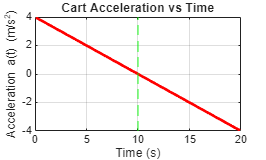

figure(2);
plot(t_a, a, 'r-', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Acceleration a(t) (m/s^2)');
title('Cart Acceleration vs Time');
xline(10,'g--','LineWidth',1);
grid on;

5. Identify the time when speed is maximized and interpret what acceleration is near that time

[v_max, idx_max] = max(v);
t_max = t(idx_max);  % time of maximum speed
a_at_max = a(idx_max-1);  % approximate acceleration near max speed
fprintf('Maximum speed = %.2f m/s occurs at t = %.2f s\n', v_max, t_max);

Maximum speed = 20.00 m/s occurs at t = 10.00 s


fprintf('Acceleration near max speed ≈ %.2f m/s^2\n', a_at_max);

Acceleration near max speed ≈ 0.04 m/s^2
